# ValueAtRisk

**Overview**

The `ValueAtRisk` chart displays the distribution of a given return series using a histogram. The chart also displays a non-parametric kernel-smoothed probability density fit (computed using `fitdist`) and two vertical lines indicating the empirical value at risk and conditional value at risk.

- The $x%$ value at risk is the $(100-x)$th percentile of the return series data. For example, the $95\%$ value at risk can be computed by taking the $5$th percentile of the return series values `r` . In `MATLAB` code, `VaR = prctile( r, 5 )`. 

- The $x%$ conditional value at risk is the mean of the returns which are less than the $x%$ value at risk. For example, the $95\%$ conditional value at risk can be computed as:  `CVaR = mean( r( r < VaR ) )`, where `VaR` is the $95\%$ value at risk.

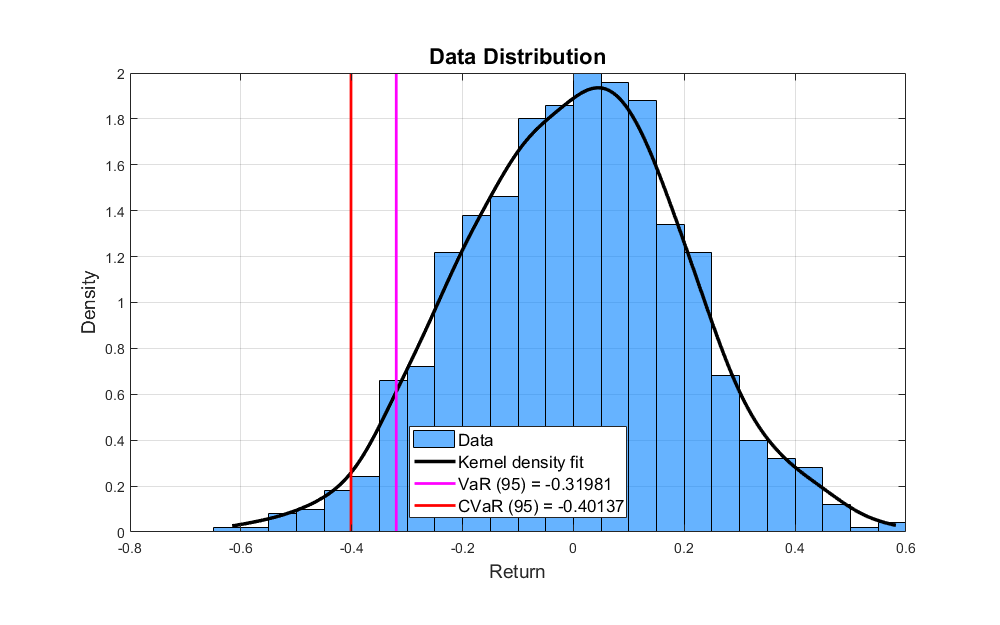

The chart data comprises a numeric vector (`Data`). The value at risk threshold is set using the `VaRLevel` property of the chart (the default value is 0.95, corresponding to a $95\%$ threshold). 

**Resources**

[Open](matlab: edit(fullfile(galleryRoot, '+Examples', 'ValueAtRisk.mlx'))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(galleryRoot, '+Charts', 'ValueAtRisk'))) the source code for the `ValueAtRisk` chart.

Documentation for [fitdist](matlab: web(fullfile(matlabroot, 'help', 'stats', 'fitdist.html'), '-helpbrowser')).

Copyright 2018 The MathWorks, Inc.

## Import the chart.

import Charts.ValueAtRisk

## Create sample return series data from a t-distribution for the chart.

rng default
d = 0.02 * trnd(10, 2000, 1 );

## Create a figure for the chart.

f = galleryFigure( 'Name', 'ValueAtRisk Example' );

## Create the chart.

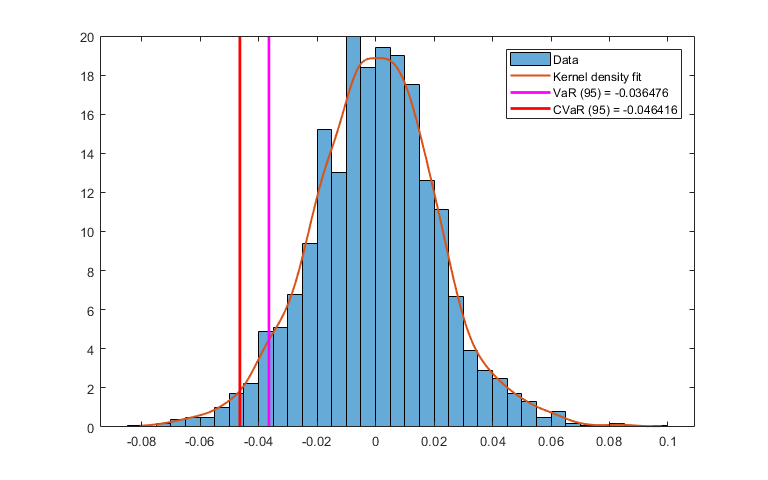

VR = ValueAtRisk( 'Parent', f, 'Data', d );

## Annotate the chart.

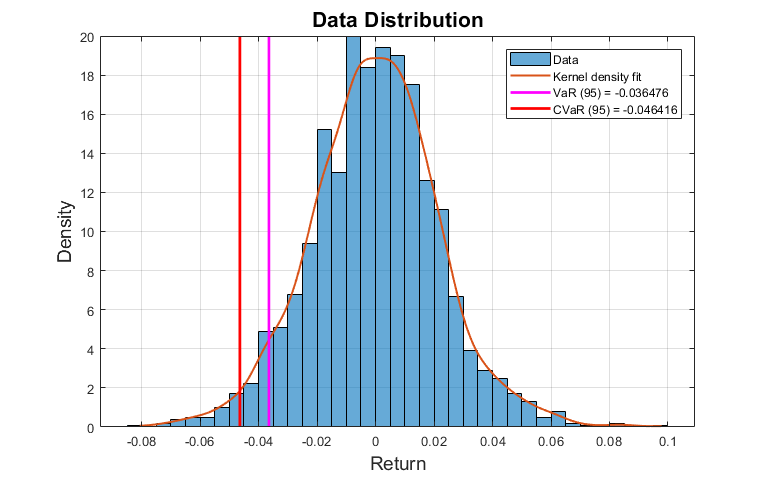

set( VR.XLabel, 'String', 'Return', 'FontSize', 14 )
set( VR.YLabel, 'String', 'Density', 'FontSize', 14 )
set( VR.Title, 'String', 'Data Distribution', 'FontSize', 16 )
VR.Grid = 'on';

## Adjust the density plot.

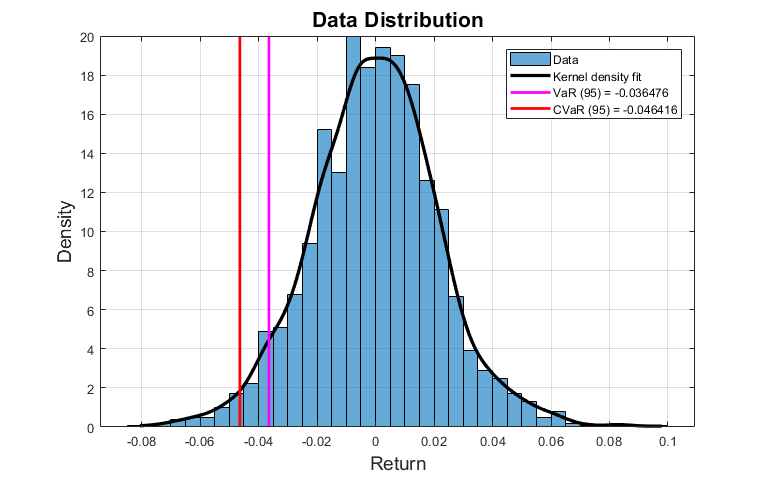

VR.DensityWidth = 2.5;
VR.DensityColor = 'k';

## Change the bar color and transparency.

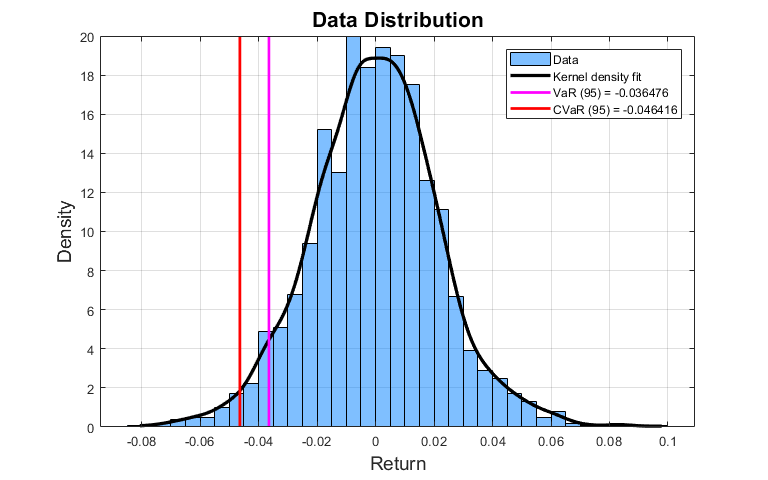

VR.FaceColor = [0, 0.5, 1];
VR.FaceAlpha = 0.5;

## Customize the legend.

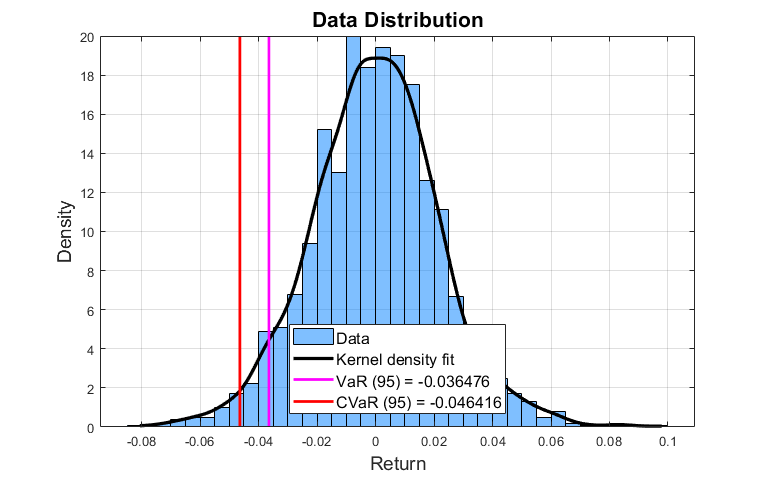

VR.LegendFontSize = 12;
VR.LegendLocation = 'south';

## Adjust the value at risk level.

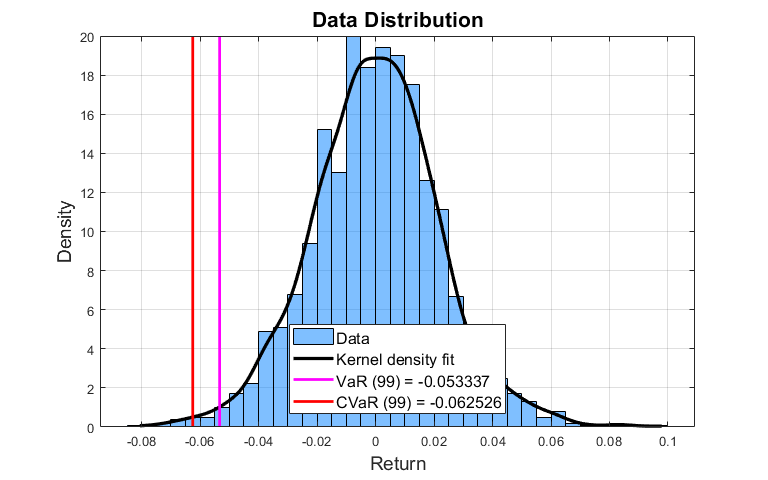

VR.VaRLevel = 0.99;

## Update the chart data and value at risk level.

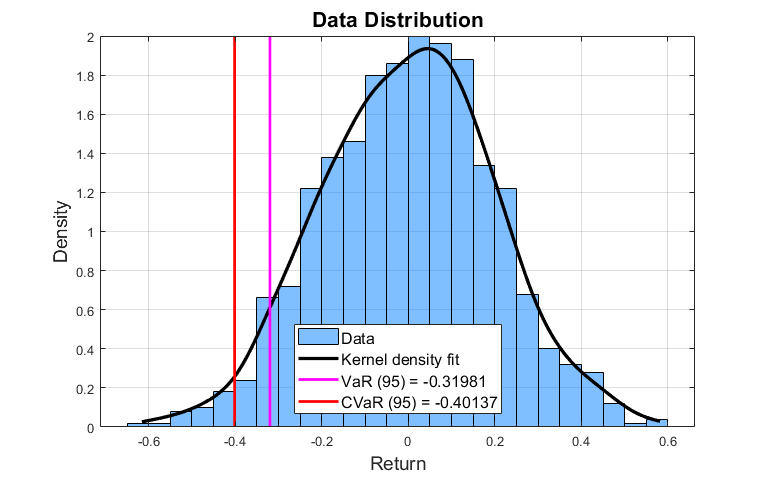

newData = 0.20 * randn( 1000, 1 );
VR.Data = newData;
VR.VaRLevel = 0.95;